# Tarea 1b

Ricardo Camacho Castillo 

A01654132

clc,clear

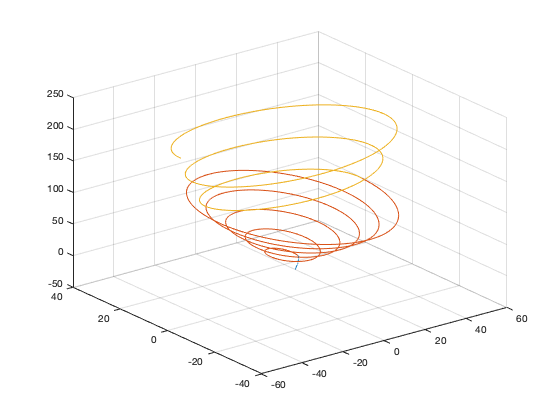

a = 5;
b = 1;
c = 5;

%t1 = 0:0.01:a;

t1 = linspace(0,a,1000);

x1 = t1;
y1 = (b/a).*t1 - sqrt(a-t1);
z1 =  2*b.*t1 - sqrt(a-t1);

plot3(x1,y1,z1)
hold on
grid on

%t2 = a:0.01:a+2*c*pi;

t2 = linspace(a,a+2*c*pi,1000);

x2 =  t2.*cos(b.*(t2-a));
y2 =  b + t2.*sin(b.*(t2-a));
z2 =  2*a*b + 3.*(t2-a);

plot3(x2,y2,z2)

%t3 = a+2*c*pi:0.01:a+3*c*pi;

t3 = linspace(a+2*c*pi,a+3*c*pi,1000);

x3 =  t3.*cos(b.*(t3-a-2*c*pi));
y3 =  b + 0.4.*t3.*sin(b.*(t3-a-2*c*pi));
z3 =  2*a*b + 6*c*pi + 7.*(t3-a-2*c*pi);

plot3(x3,y3,z3)
hold off

x = [x1,y1,z1];
y = [x2,y2,z2];
z = [x3,y3,z3];


m1 = min(z1);
pos1min = 1;

for i = 1:1000
    cont = z1(i);
    if m1 == cont      
        break
    end
    pos1min = pos1min + 1;
end


m2 = min(z2);
pos2min = 1;

for i = 1:1000
    cont = z2(i);
    if m2 == cont      
        break
    end
    pos2min = pos2min + 1;
end


m3 = min(z3);
pos3min = 1;

for i = 1:1000
    cont = z3(i);
    if m3 == cont      
        break
    end
    pos3min = pos3min + 1;
end


m1 = max(z1);
pos1max = 1;

for i = 1:1000
    cont = z1(i);
    if m1 == cont      
        break
    end
    pos1max = pos1max + 1;
end


m2 = max(z2);
pos2max = 1;

for i = 1:1000
    cont = z2(i);
    if m2 == cont      
        break
    end
    pos2max = pos2max + 1;
end


m3 = max(z3);
pos3max = 1;

for i = 1:1000
    cont = z3(i);
    if m3 == cont      
        break
    end
    pos3max = pos3max + 1;
end

El mínimo en x(t) es:

[x1(pos1min),y1(pos1min),z1(pos1min)]

ans =          0   -2.2361   -2.2361


El mínimo en y(t) es:

[x2(pos2min),y2(pos2min),z2(pos2min)]

ans =      5     1    10


El mínimo en z(t) es:

[x3(pos3min),y3(pos3min),z3(pos3min)]

ans =    36.4159    1.0000  104.2478


El máximo en x(t) es:

[x1(pos1max),y1(pos1max),z1(pos1max)]

ans =      5     1    10


El máximo en y(t) es:

[x2(pos2max),y2(pos2max),z2(pos2max)]

ans =    36.4159    1.0000  104.2478


El máximo en z(t) es:

[x3(pos3max),y3(pos3max),z3(pos3max)]

ans =   -52.1239    1.0000  214.2035


syms x(t) y(t) z(t) dx(t) dy(t) dz(t) r(t) T(t) N(t) B(t)

p1 = a + 2*(c-1)*pi + pi/4;

if (p1<a)
    x(t)=t;
    y(t)=(b/a)*t - sqrt(a-t);
    z(t)=2*b*t - sqrt(a-t);
elseif (p1<(a+2*c*pi) && p1>a)
    x(t)=t*cos(b*(t-a));
    y(t)=b + t*sin(b*(t-a));
    z(t)=2*a*b + 3*(t-a);
else
    x(t)=t*cos(b*(t-a-2*c*pi));
    y(t)=b + 0.4*t*sin(b*(t-a-2*c*pi));
    z(t)=2*a*b + 6*c*pi + 7*(t-a-2*c*pi);
end


r = [x;y;z];

dr = diff(r);
T = dr/norm(dr);

dT = diff(T);
N = dT/norm(dT);

B = cross(T,N);

TU = round(T(p1),6)

$$TU = \left(\begin{array}{c} -0.680685\\ 0.726189\\ 0.096527 \end{array}\right)$$

NU = round(N(p1),6)

$$NU = \left(\begin{array}{c} -0.729798\\ -0.683656\\ -0.003101 \end{array}\right)$$

BU = round(B(p1),6)

$$BU = \left(\begin{array}{c} 0.063739\\ -0.072556\\ 0.995326 \end{array}\right)$$